# Tensor decomposition and entanglement entropy

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will decompose a high-rank tensor into a matrix product state (MPS) that consists of rank-2 and -3 tensors, by using the QR decomposition or the singular value decomposition (SVD).

Let's define a rank-5 tensor acting onto five subsystems, whose dimensions are 2, 3, 2, 3, and 4, respectively.

clear
sz = [2 3 2 3 4]; % local space dimensions
T = reshape((1:prod(sz)),sz); % rank-5 tensor
T = T/norm(T(:)); % normalize

Here `T` is normalized by its norm. Note that, for the computation of the norm, it's necessary to take a linearized form of the tensor by using `(:)`.

I will demonstrate the decomposition of the tensor "from left to right", i.e., decomposing a tensor for the first leg, then for the second, and so on, by using the QR decomposition:

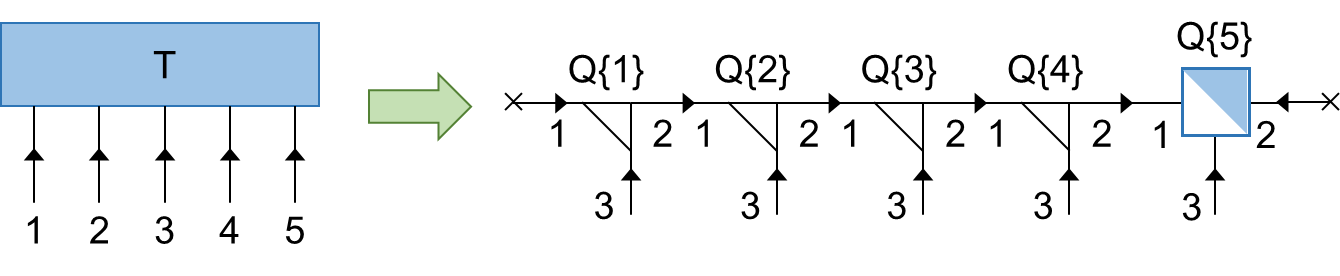

The numbers next to the tensor legs indicate the order of the legs. A left-unitary matrix obtained after the $n$-th QR decomposition are reshaped and stored in the $n$-th cell `Q{n}`. At the last iteration (i.e., the fourth iteration), we dump the remaining tensor into `Q{5}`. For `Q{1}` and `Q{5}`, we assign the dummy legs of dimension 1, indicated by the x symbols at the ends. By introducing the dummy legs, we can treat all the tensors `Q{n}` as rank-3, which simplifies the code writing.

Q = cell(1,numel(sz));
R = T; % temporary tensor to be QR-decomposed
szl = 1; % the bond dimension of the left leg of Q{n} to be obtained after
% the QR decomposition at iteration n; for n = 1, szl = 1 for the dummy leg
for it = (1:(numel(sz)-1))
    R = reshape(R,[szl*sz(it), prod(sz(it+1:end))]);
    [Q{it},R] = qr(R,0);
    Q{it} = reshape(Q{it},[szl, sz(it), numel(Q{it})/szl/sz(it)]);
    Q{it} = permute(Q{it},[1 3 2]); % permute to the left-right-bottom order
    szl = size(Q{it},2); % update the bond dimension
    R = reshape(R,[szl,sz(it+1:end)]);
end
Q{end} = permute(R,[1 3 2]);

Note we use the thin QR decomposition by setting the second input argument to `qr` as `0`.

Check the dimensions of tensors in the MPS.

Q

Q = 1×5 cell array
    {1×2×2 double}    {2×6×3 double}    {6×12×2 double}    {12×4×3 double}    {4×1×4 double}


Note that the MATLAB automatically truncates the trailing singleton dimension, so the dummy leg dimension of `Q{5}` is not displayed.

## Exercise (a): Check the integrity of the tensor decomposition

Contract the tensors `Q{1}`, ..., `Q{5}` to make a rank-5 tensor again. Check whether the contraction result is the same as the original tensor `T`.

## Exercise (b): Entanglement entropies for different bipartitions

Compute the entanglement entropy $S_{\mathrm{A}/\mathrm{B}}$ for the following three ways of bipartitioning the tensor `T`'s fives legs into two sets, A and B:

(i) A = {1, 2}, B = {3, 4, 5};

(ii) A = {1, 3}, B = {2, 4, 5};

(iii) A = {1, 5}, B = {2, 3, 4}.

## Exercise (c): Use the SVD for the tensor decomposition and compute the entanglement entropy

Let's consider the same tensor `T` defined above. Apply the series of the SVD from left to right to decompose `T` into an MPS, represented by a cell array `M`.

- At each step $n$ of the SVD, compute the entanglement entropy $S_n = - \sum_i s_i^2 \log_2 (s_i^2)$ by using the singular values $\{ s_i \}$. What are the values of $S_n$ for different iterations?

- After the SVD, truncate the decomposed components associated with the singular values smaller than the double precision accuracy limit `eps`. How do the size of tensors `M{n}` differ from the above results `Q{n}`? 

- Similarly as in Exercise (a), check whether the contraction of `M{n}`'s reproduce the original tensor `T`.